# Note 4

Domain decomposition method (DDM) is an iterative method which aims to solve a BVP by divide-and-conquer. Let us define our original or direct problem as 


$$P\left(u;g\right)\left\lbrace \begin{array}{ll}
F\left(u\left(x\right)\right)=0 & x\in \Omega \;\\
u\left(x\right)=g & x\in \Gamma :=\partial \;\Omega \;
\end{array}\right.$$


You first divide the domain $\Omega$ into overlapping subsets of the original $\Omega_1 ,\dots ,\Omega_{N_d }$. Some portion of the boundary $\partial \;\Omega_i$ may coincide with the original boundary $\Gamma$, hence we define this region $\Gamma_i :=\partial \;\Omega_i \cap \Gamma$. The remaining portion of the boundary are newly introduced by decomposition so we call them artificial interfaces. If domain $\Omega_j$ intersects, we define the artificial interface w.r.t. $\Omega_i$ as $\Gamma_{\textrm{ij}} =\partial \;\Omega_i \cap \bar{\Omega_j }$. 

You must have local problems on each subdomain that are

- independent of the other problems 

- well-posed regardless of the data on the artificial interfaces 

For example, if we define


$$P_i \left(u_i ;g,g_{\textrm{ij}} \right)=\left\lbrace \begin{array}{ll}
F_i \left(u_i \left(x\right)\right)=0 & x\in \Omega_i \\
u_i \left(x\right)=g & x\in \Gamma_i \\
u_i \left(x\right)=g_{\textrm{ij}}  & x\in \Gamma_{\textrm{ij}} ,\forall \;j
\end{array}\right.$$


then $P_i$ must be well-posed regardless of $g_{\textrm{ij}}$. 

## Algorithm 

The original DDM a.k.a the Schwarz alternating procedure : 

- Solve $P_i \left(u_i^{\left(0\right)} ,g,0\right)$$,\forall \;i\;$

- Let $g_{\textrm{ij}}^{\left(n+1\right)} ={u_j }^{\left(n\right)} {\left|\right.}_{\Gamma_{\textrm{ij}} }$

- For $n=1\;\textrm{to}\;n_{\max }$, 

-     solve $P_i \left(u_i^{\left(n\right)} ,g,g^{\left(n-1\right)} \right)$$,\forall \;i\;$

If the method is convergent, then the piecewise function $u^{\left(n_{\max } \right)}$ consisting of the union of the final solutions from each subdomain will be a good approximation of the solution to the original problem. 

This is the most abstract form of the DDM. Modern DDM do not follow these steps explicitly because they are more efficient techniques. Here, however, we follow these exact steps. 

## Grid

The standard way of implementing overlapping DDM (ODDM) is to first create non-overlapping domains. We create a clear division between the domains. Then we decide how far each domain protrudes over the dividing lines. The level of protrusion is a parameter. 

In 1D, constructing the grid is simple. You start with a base number of nodes to assign to each subdomain $N_{\textrm{base}}$. You want even work distribution. You can compute the total number of nodes with $N_{\textrm{total}} =N_d \;\left(N_{\textrm{base}} +1\right)-1$. The interface nodes are the nodes that lie directly in the "middle" of two overlapping subdomains. The nodal index of the $i$th interface node is ${\textrm{int}}_i =i\left(N_{\textrm{base}} +1\right)$. Let $N_o$ be the number of nodes that subdomains protrude beyond the interfaces. Then each subdomain will have $N_{\textrm{base}} +2\left(N_o +1\right)$ nodes except the first and last domains which will have $N_{\textrm{base}} +N_o +1$ nodes.  

% parameters:
% num_domains = 3;    % # of subdomains
% num_base = 5;
% num_total = (num_base+1)*num_domains-1; % number of nodes for direct problem
% overlap = 1;
% range = zeros(num_domains,2); % starting and ending nodal indeces for each domain
% int = (num_base+1)*(1:num_domains-1); % index of nodes
% 
% figure
% hold on
% for i = 1:num_domains
%     if (i==1)
%         range(1,1) = 1;
%         range(1,2) = int(1)+overlap;
%     elseif(i==num_domains)
%         range(end,1) = int(end)-overlap;
%         range(end,2) = num_total;
%     else
%         range(i,1) = int(i-1)-overlap;
%         range(i,2) = int(i)+overlap;
%     end
%     nodes = range(i,1):range(i,2);
%     n = length(nodes);
%     plot(nodes, i*ones(n,1),'o-','LineWidth',1.5)
% end
% 
% for i = 1:num_domains-1
%     xline(int(i))
% end
% ylim([0, num_domains+1])
% yticks(0:num_domains+1)
% xlabel('Nodal Index')
% ylabel('Domain')
% title(sprintf('Base = %d\nDomains = %d\nOverlap=%d',num_base,num_domains,overlap))

There is a global index for the nodes on the mesh. The plot shows index of the nodes assigned to each subdomain. 

The vertical black lines indicate the location of the interface nodes. 

When we want to exchange data at $\Gamma_{\textrm{ij}} =\partial \;\Omega_i \cap \bar{\Omega_j }$, we simply know to send the data left or right. Suppose the mesh of $\Omega_i$ has $N_i$ nodes. Then the solution at the $\left(1+2N_o \right)\textrm{th}\;$node gets passed to the left domain and the solution at the $\left(N_i -2N_o \right)\textrm{th}$ node gets passed to the right domain. 

## Gaussian Curvature Problem

We will apply the DDM to the Gaussian curvature problem in Note 1. We use the same discretization of $\ddot{u} \left(x\right)-{\left(1+\dot{u} {\left(x\right)}^2 \right)}^{\frac{3}{2}} =0$. Let us choose some DDM parameters. 

num_base = 20;
num_dom = 3;
overlap = 4;
num_total = (num_base+1)*num_dom -1;

We can solve the direct problem. The same discretization function can be used in the DDM. We only need to change the boundary condition input. 

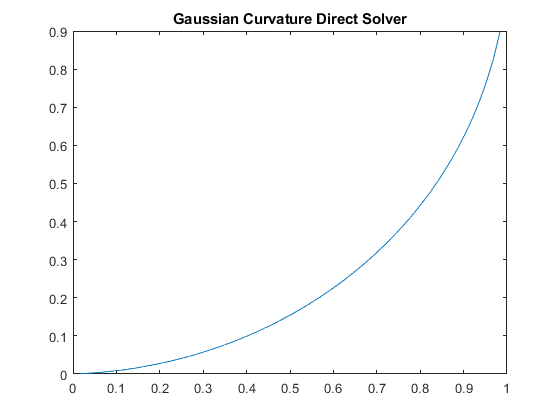

a = 0; b = 1;
ga = 0; gb = 1;
exact =@(x) -sqrt(1-x.^2)+1;

h = (b-a)/(num_total+1);
X = a+h:h:b-h;
f =@(u) D(u,ga,gb,h);

% direct solver
U_direct = zeros(size(X));
U_direct = fsolve(f,U_direct,optimoptions('fsolve','Display','off')); % use nonlinear solver from optimization toolbox

figure
plot(X,U_direct)
title('Gaussian Curvature Direct Solver')

## DDM Implementation

In order to properly implement ODDM, we need to be able to each local problem with the proper node indexing. 

In general we need:

- the mesh for each subdomain

- the mapping between local to global indexing of the nodes 

- nodal mapping between overlapping domains

- adjacency information of subdomains 

These requirements are easy in 1D if we enforce a uniform mesh. It's sufficient to know the global indeces of the beginning and ending nodes for each domain. The mesh, mapping, and data sharing information can be derived. 

x_i = cell(num_dom,1); % mesh of subdomain
u_i = cell(num_dom,1); % cell of solutions from each dom

range = zeros(num_dom,2);         % index of starting and ending nodes for each domain
int = (num_base+1)*(1:num_dom-1); % index of interface nodes

for i = 1:num_dom
    if (i==1)
        range(1,1) = 1;
        range(1,2) = int(1)+overlap;
    elseif(i==num_dom)
        range(end,1) = int(end)-overlap;
        range(end,2) = num_total;
    else
        range(i,1) = int(i-1)-overlap;
        range(i,2) = int(i)+overlap;
    end
    nodes = range(i,1):range(i,2);
    x_i{i} = a+h*nodes; % create the grid for each domain
    u_i{i} = nodes*0;
end

We also need to keep track of the dirichlet data at each iteration. Keeping a record of the allows us to compute the residual. 

max_itr = 300;
g_data = zeros(num_dom,2,max_itr+1); % left & right dirichlet data for each dom, and for each iteration
g_data(1,1,:) = ga;  % left data of domain 1
g_data(end,2,:) = gb; % right data of last domain

opt = optimoptions('fsolve','Display','off'); % options for fsolve

For simplicity, we run the DDM for a fixed number of iterations. It's better to do a while loop. 


for n = 1:max_itr % DDM Iteration
    
    for i = 1:num_dom
        u_i{i} = fsolve(@(u) D(u,g_data(i,1,n),g_data(i,2,n),h),u_i{i},opt);
    end
    
    g_data(1,2,n+1) = u_i{2}(1+2*overlap); % right BD for domain 1
    for i = 2:num_dom-1
        g_data(i,1,n+1) = u_i{i-1}(end-2*overlap); % Left BD from previous domain
        g_data(i,2,n+1) = u_i{i+1}(1+2*overlap); % Right BD from next domain
    end
    g_data(end,1,n+1) = u_i{end-1}(end-2*overlap); % left BD for last domain
    
    
    %% optional - use the whole overlap as initial guess for next fsolve
    if(1) && (n<max_itr)
        for i = 1:num_dom-1
            temp = u_i{i}(end-2*overlap:end); % save a copy of the end values
            u_i{i}(end-2*overlap:end) = u_i{i+1}(1:1+2*overlap);
            u_i{i+1}(1:1+2*overlap) = temp;
        end
    end
end


## Visualizing the Result 

The first plot is the DDM solution (mutli-color) compared to the direct solution (dashed line). 

% figure, hold on
% plot(X,U_direct,'k--','LineWidth',2)
% for i = 1:num_dom
%     plot(x_i{i},u_i{i},'LineWidth',2)
% end
% title(sprintf('DDM Solution after %d Iterations',max_itr))
% xlabel('x'), ylabel('u(x)')

The 2nd plot shows the residual. Therer are many ways to define a residue but it is generally some measure of the change in boundary data. Usually, DDM uses the residue as the stopping criterion instead of a fixed number. Here, I will define the residue as:


$$r_n =\sum_i \left|g_i^{\left(n+1\right)} -g_i^{\left(n\right)} \right|\;$$


which is the sum, over all domains, of the absolute change in the boundary data after 1 iteration. If the plot shows decreasing residue, then the method is converging.     

% residue = zeros(max_itr,1);
% for n = 1:max_itr
%     res = 0;
%     for i = 1:num_dom
%         res = res + sum(abs( g_data(i,:,n)-g_data(i,:,n+1) ));
%     end
%     residue(n) = res;
% end
% 
% figure
% plot(1:max_itr,residue,'*-','LineWidth',1.5)
% xlabel('Iteration')
% ylabel('Residue')
% title('Change in boundary data per Iteration')

function F = D(u,c1,c2,h)
N = length(u);
F = zeros(N,1);
ih2 = 1/h^2;

F(1) = ih2*(u(2)-2*u(1)+c1)-(1+ih2*max([u(1)-c1,u(1)-u(2),0])^2)^(3/2);
for j = 2:N-1
    F(j) = ih2*(u(j+1)-2*u(j)+u(j-1))-(1+ih2*max([u(j)-u(j-1),u(j)-u(j+1),0])^2)^(3/2);
end
F(N) = ih2*(c2-2*u(N)+u(N-1))-(1+ih2*max([u(N)-u(N-1),u(N)-c2,0])^2)^(3/2);
end

%% 
% D_ddm is the discretization of the BVP with Nd subdomains.
% The delta controls the overlap, delta >= 0.
% int is an array of length Nd-1 which specifies the interface points
function F = D_ddm(u,c1,c2,h,Nd,delta,int)

% the solution u is length n, the # of unknowns
n = length(u); 

%



end